% Implementation of a Simple linear Regression with one variable

data = load('data.txt');

X = data(:, 1); y = data(:, 2);
m = length(X); % number of training examples

% Plot the Data 

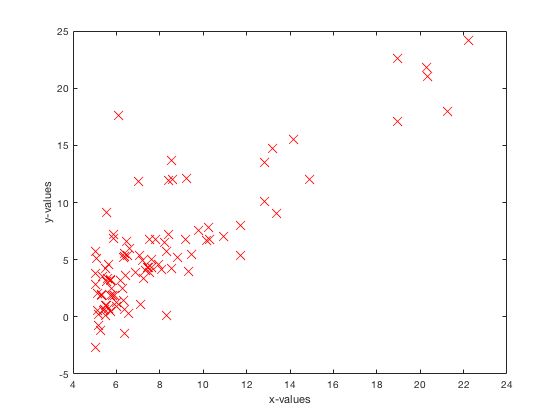

plotData(X, y);

% Cost and Gradient descent

X = [ones(m, 1), data(:,1)]; % Add a column of ones to x
theta = zeros(2, 1); % initialize fitting parameters

% Gradient descent settings
iterations = 1500;
alpha = 0.01;

% Compute and display initial cost
J = computeCost(X, y, theta);

fprintf('With theta = [0 ; 0]\nCost computed = %f\n', J);

With theta = [0 ; 0]
Cost computed = 32.072734


% Gradient descent
theta = gradientDescent(X, y, theta, alpha, iterations);

fprintf('Theta found by gradient descent:\n');

Theta found by gradient descent:


fprintf('%f\n', theta);

-3.630291
1.166362


% Visualizing J(theta_0, theta_1)

fprintf('Visualizing J(theta_0, theta_1) ...\n')

Visualizing J(theta_0, theta_1) ...


% Grid over which we will calculate J
theta0_vals = linspace(-10, 10, 100);
theta1_vals = linspace(-1, 4, 100);

J_vals = zeros(length(theta0_vals), length(theta1_vals));
for i = 1:length(theta0_vals)
    for j = 1:length(theta1_vals)
	  t = [theta0_vals(i); theta1_vals(j)];
	  J_vals(i,j) = computeCost(X, y, t);
    end
end

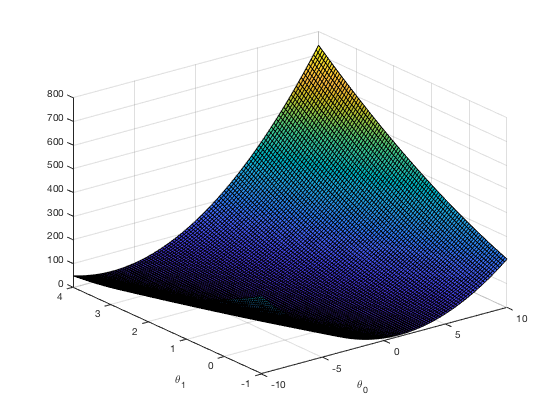

% Surface plot
figure;
surf(theta0_vals, theta1_vals, J_vals)
xlabel('\theta_0'); ylabel('\theta_1');

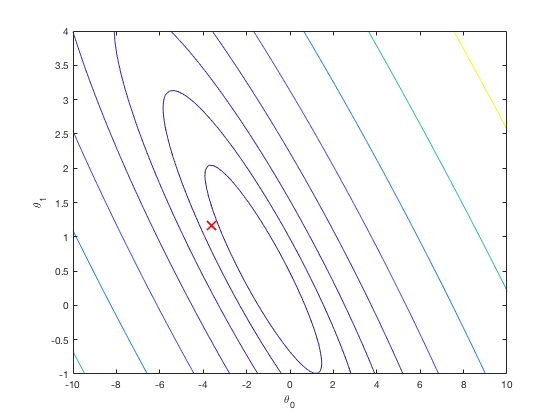

% Contour plot
figure;
% Plot J_vals as 15 contours spaced logarithmically between 0.01 and 100
contour(theta0_vals, theta1_vals, J_vals, logspace(-2, 3, 20))
xlabel('\theta_0'); ylabel('\theta_1');
hold on;
plot(theta(1), theta(2), 'rx', 'MarkerSize', 10, 'LineWidth', 2);